Let's try out the Euler and backward Euler time stepping methods using the second-order semidiscretization:

m = 100;  [x,Dx,Dxx] = diffper(m,[0,1]);
Ix = eye(m);

First we apply the Euler discretization. 

tfinal = 0.05;  n = 500;  
tau = tfinal/n;  t = tau*(0:n)';
U = zeros(m,n+1);

This is where we set the initial condition. It isn't mathematically periodic, but the end values and derivatives are so small that for numerical purposes it may as well be.

U(:,1) = exp( -60*(x-0.5).^2 );

The Euler time stepping simply multiplies by a constant matrix for each time step.

A = Ix + tau*Dxx;
for j = 1:n
    U(:,j+1) = A*U(:,j);
end

Things seem to start well.

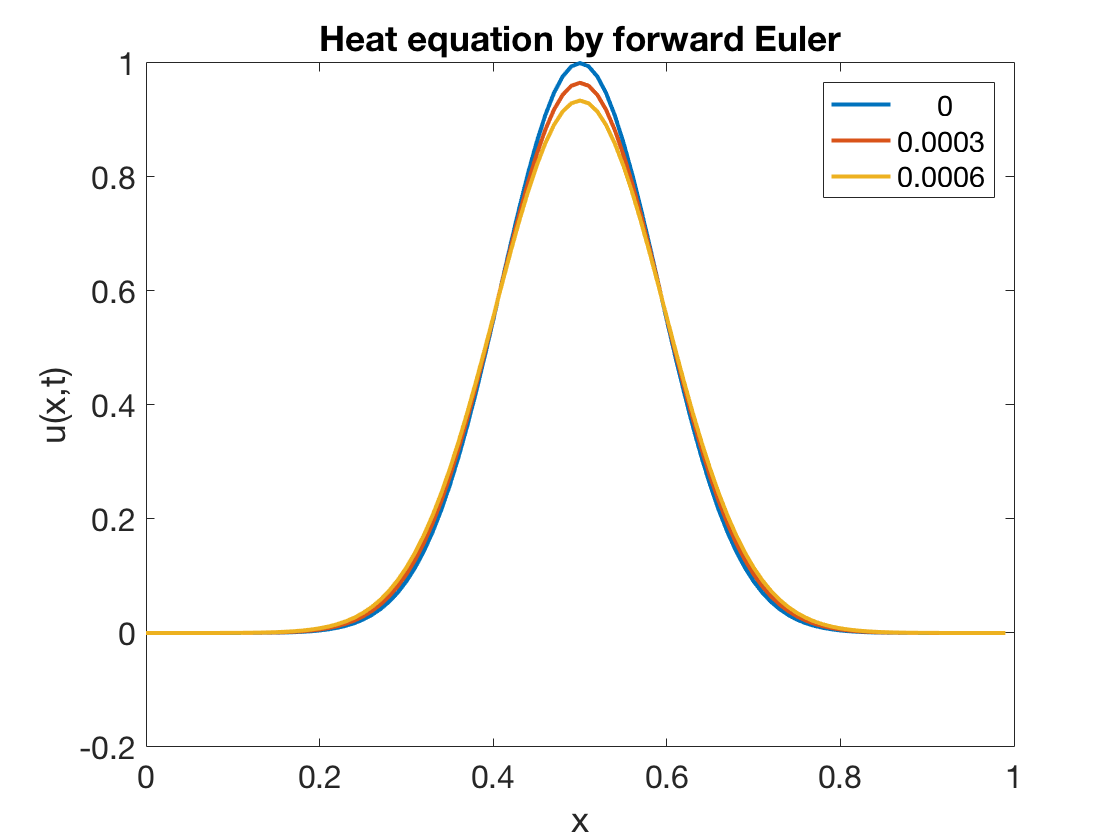

plot(x,U(:,1:3:7))
xlabel('x'), ylabel('u(x,t)')   % ignore this line
warning off    % ignore this line
legend(num2str(t(1:3:10)))   % ignore this line
title('Heat equation by forward Euler')   % ignore this line

Shortly thereafter, though, there is nonphysical growth. 

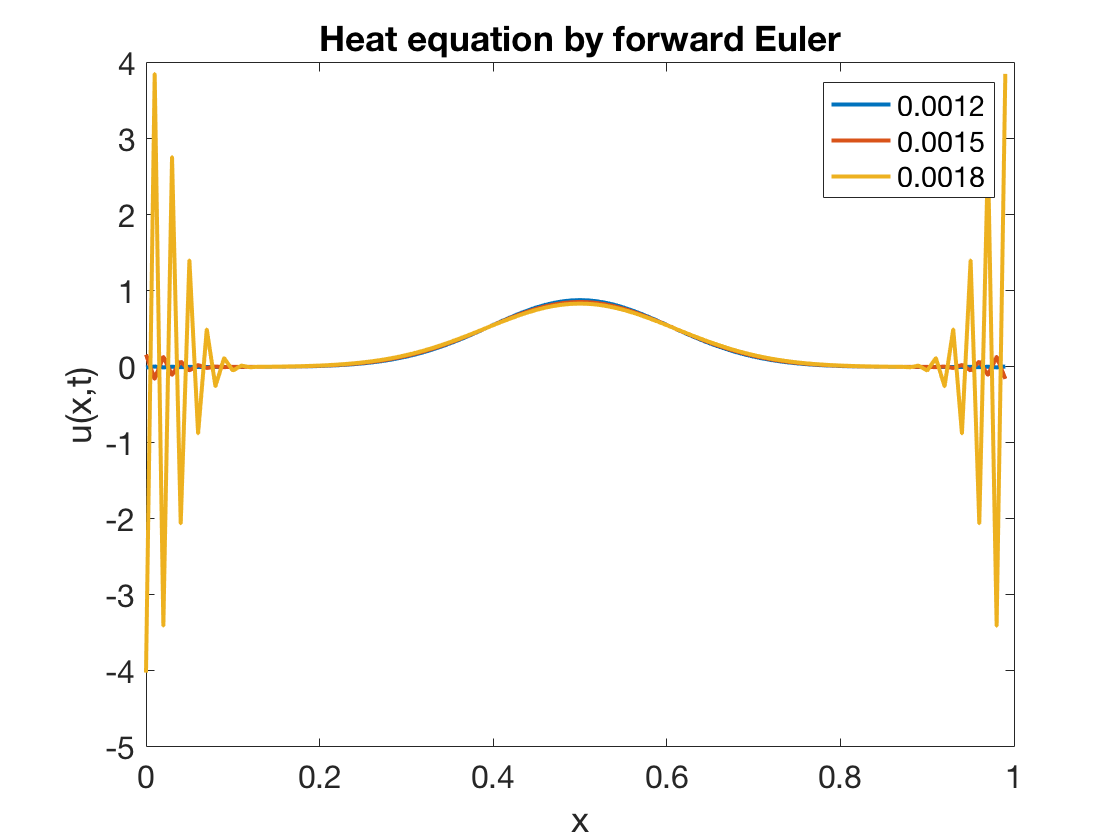

cla
plot(x,U(:,13:3:19))
xlabel('x'), ylabel('u(x,t)')   % ignore this line
legend(num2str(t(13:3:19)))   % ignore this line
title('Heat equation by forward Euler')   % ignore this line

The growth is exponential in time.

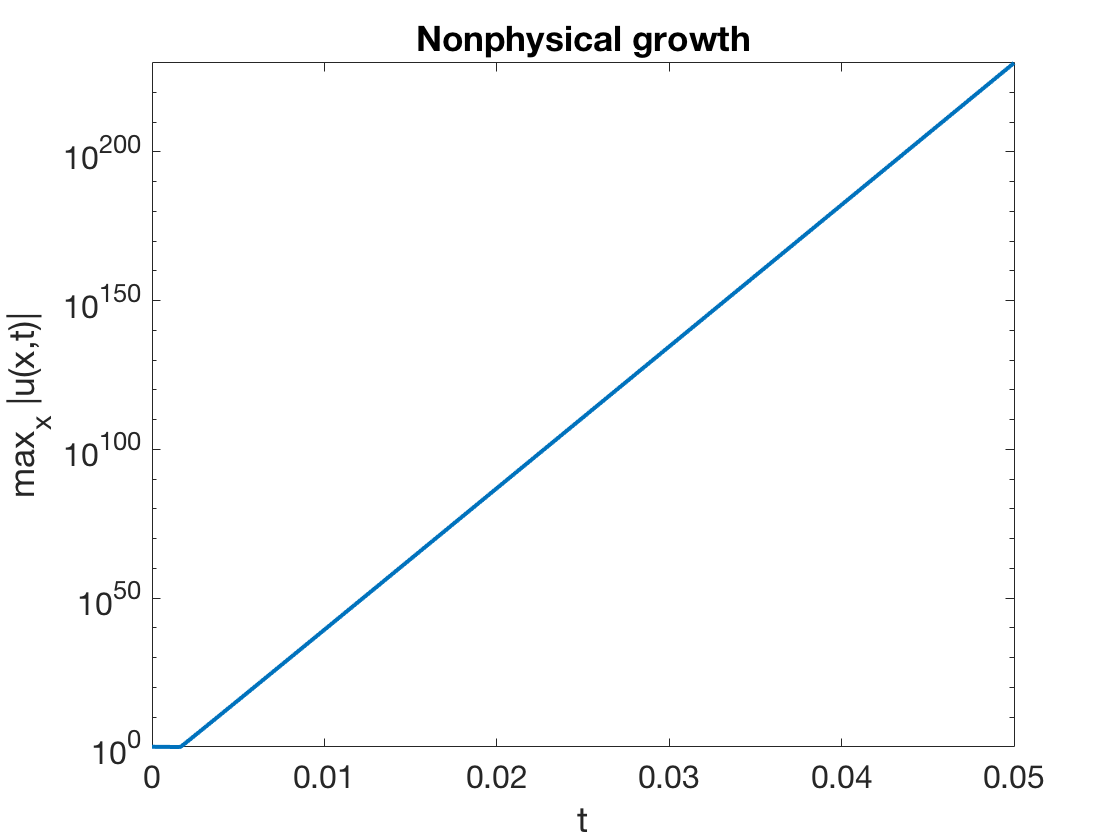

M = max( abs(U), [], 1 );     % max in each column
semilogy(t,M)
xlabel('t'), ylabel('max_x |u(x,t)|')   % ignore this line
axis tight    % ignore this line
title('Nonphysical growth')   % ignore this line

Now we try backward Euler. In this case there is a tridiagonal linear system to solve at each time step. We will use a sparse matrix to get sparse LU factorization, although the time savings at this size are negligible.

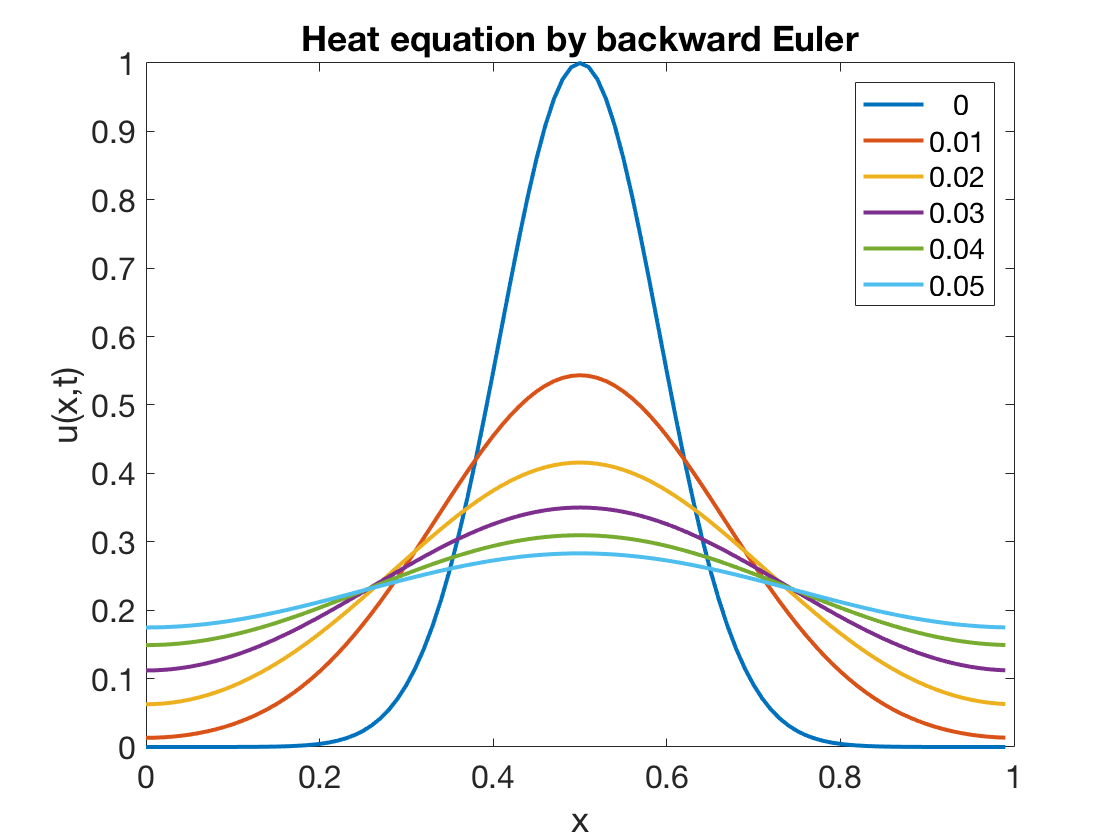

B = sparse(Ix - tau*Dxx);
for j = 1:n
    U(:,j+1) = B\U(:,j);
end
plot(x,U(:,1:100:501))
xlabel('x'), ylabel('u(x,t)')   % ignore this line
legend(num2str(t(1:100:501)))   % ignore this line
title('Heat equation by backward Euler')   % ignore this line

This solution looks physically realistic, as the large concentration in the center diffuses outward. Observe that the solution remains periodic in space. 